# **EllipticK**

Complete elliptic integral of the first kind 

## Definition


$$K\left(m\right)\equiv \mathit{\mathbf{F}}\left(1\left|m\right.\right)=F\left(\frac{\pi }{2}|m\right)$$



$$\mathit{\mathbf{K}}\left(k\right)\equiv K\left(k^2 \right)$$


where *k *is the modulus, *m *is the parameter.

Domain: $1-m\ge 0$,(or $|k|\le 1$). For the specified domain, the  codomain is real numbers.

Special values:

$K\left(-\infty \right)=0,$   $K\left(0\right)=\frac{\pi }{2}$,   $K\left(1\right)=\infty$

## Syntax

Y = EllipticK(K)

y = elK(k)

Y = mEllipticK(M)

y = melK(m)

## Description

**Y = EllipticK(K)** returns the value of the complete elliptic integral of the first kind $\mathit{\mathbf{K}}\left(k\right)$ for each element of the array  K (modulus).  K must be real array or scalar. **EllipticK** is the wrapper function which calls the functions **elK** element-wise via the function **ufun1**.

**y = elK(k)** returns the value of the complete elliptic integral of the first kind  $\mathit{\mathbf{K}}\left(k\right)$ for  the modulus k. It is assumed that  k is real scalars without check. y is NaN if k is invalid or convergence failed. **elK** is the wrapper function which calls the functions **melK**.

**Y = mEllipticK(M)** returns the value of  the complete elliptic integral of the first kind $K\left(m\right)$ for each element of the array  M (parameter).  M must be real array or scalar. **mEllipticK** is the wrapper function which calls the functions **melK** element-wise via the function **ufun1**.

**y = melK(m)** compute value of  the complete elliptic integral of the first kind $K\left(m\right)$ for  the parameter m. It is assumed that  m is real scalars without check. y is NaN if m is invalid or convergence failed.  **melK **call the Carlson's function **rf **for calculation of $K\left(m\right)$ ([1-2]).

## Precision

For  -${10}^6 <m$<1 the relative error of **melK  **is less than ${10}^{-15}$ .

## **Numerical Examples**

**Scalar input**

format long
k = 0.5 % |k|<= 1

k = 0.5000

[elK(k), EllipticK(k), melK(k^2), mEllipticK(k^2)]

ans =    1.685750354812596   1.685750354812596   1.685750354812596   1.685750354812596


m = 0.5; % |m|<1 
[elK(sqrt(m)), EllipticK(sqrt(m)), melK(m), mEllipticK(m)]

ans =    1.854074677301372   1.854074677301372   1.854074677301372   1.854074677301372


Accuracy. 

fprintf('%.16g\n',melK(-4)) % Maple 18D  1.009452909989211 61

1.009452909989212


Special values

melK(-inf)

ans = 0

disp(elK(0) - pi/2)

     0



elK(1)

ans = Inf

Identities

k = sqrt(2)/2;
disp(elK(k)-elCK(k))

     2.220446049250313e-16



k = sqrt(2) - 1;
disp(elCK(k) - sqrt(2)*elK(k))

     0



k = 3 - 2*sqrt(2);
disp(EllipticCK(k) - 2*EllipticK(k))

     1.332267629550188e-15



[MATLAB example](https://www.mathworks.com/help/symbolic/elliptick.html)

format short
s = [mEllipticK(1/2), mEllipticK(pi/4), mEllipticK(1),  mEllipticK(-5.5)]

s =     1.8541    2.2253       Inf    0.9325


**Vector input**

M=[sqrt(2)/2, sqrt(2) - 1, 3 - 2*sqrt(2)];
mEllipticK(M)

ans =     2.0860    1.7875    1.6456


**Matrix input**

K=[-1/2 1/3 1/4; 1/2 -1/3 -1/4];
disp(mEllipticK(K.^2)-EllipticK(K))

     0     0     0
     0     0     0



## **Plot**

**Example 1**

[MATLAB example](https://www.mathworks.com/help/symbolic/elliptick.html)

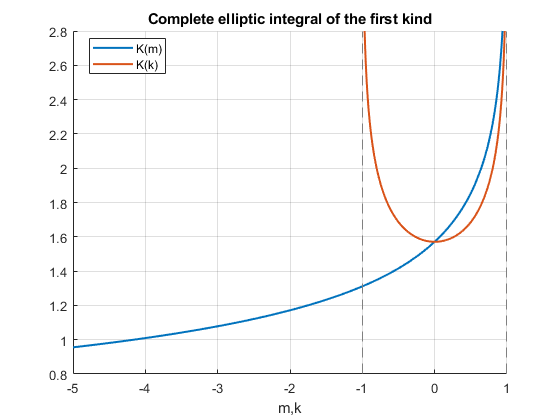

figure
hold on
fplot(@(m) mEllipticK(m),'LineWidth',1.5)
fplot(@(k) EllipticK(k),'LineWidth',1.5)
title('Complete elliptic integral of the first kind')
legend('K(m)','K(k)','Location','best')
xlabel('m,k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] B.C. Carlson, Computing Elliptic Integrals by Duplication. Numerische Mathematik 33, 1-16, 1979.

[2] W.H. Press et al., Numerical Recipes, 3rd ed., Cambridge, 2007

## See Also